# 图线的绘制与装饰

## 使用plot()函数绘制图线

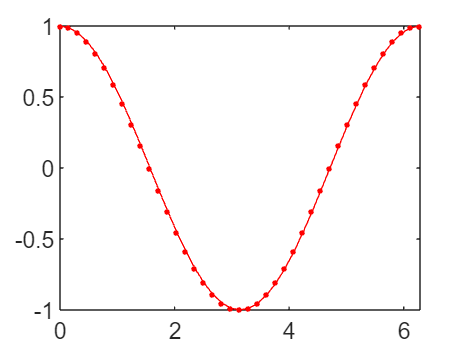

% 绘制( 0 , 2 π ) (0, 2\pi)(0,2π)内余弦函数的图像

x = 0:pi/20:2*pi; % 2*20+1个点   
y = cos(x); % 余弦函数
plot(x, y, 'r.-') % r-红色 .-点线 -实线

**线型设定|符****线型****标记|设定符****标记|颜色设定|符****颜色**

`-`实线（默认）`o`圆圈`y`黄色

`--`虚线`+`加号`m`品红色

`:`点线`*`星号`c`青蓝色

`-.`点划线`.`点`r`红色

`x`叉号`g`绿色

`s`方形`b`蓝色

`d`菱形`w`白色

`^`上三角`k`黑色

`v`下三角

`>`右三角

`<`左三角

`p`五角形

`h`六角形

## 装饰图线

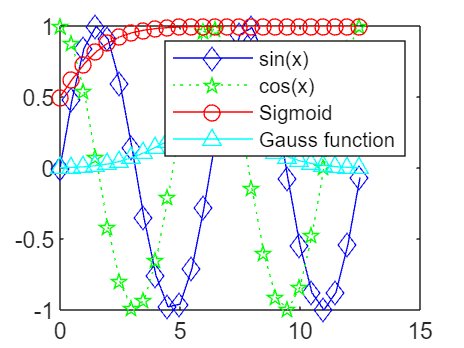

% 使用legend()函数为图片增加图例

x=0:0.5:4*pi;
y=sin(x); h=cos(x); 
w=1./(1+exp(-x)); 
g=(1/(2*pi*2)^0.5).*exp((-1.*(x-2*pi).^2)./(2*2^2));

plot(x,y,'bd-' ,x,h,'gp:',x,w,'ro-' ,x,g,'c^-');		% 绘制多条图线
legend('sin(x)','cos(x)','Sigmoid','Gauss function');	% 添加图例


% 标题&标签（坐标轴）
x = 0:0.1:2*pi; y1 = sin(x); y2 = exp(-x);
plot(x, y1, '--*', x, y2, ':o');
xlabel('t = 0 to 2\pi');
ylabel('values of sin(t) and e^{-x}')
title('Function Plots of sin(t) and e^{-x}');
legend('sin(t)','e^{-x}');


## 控制坐标轴,边框与网格

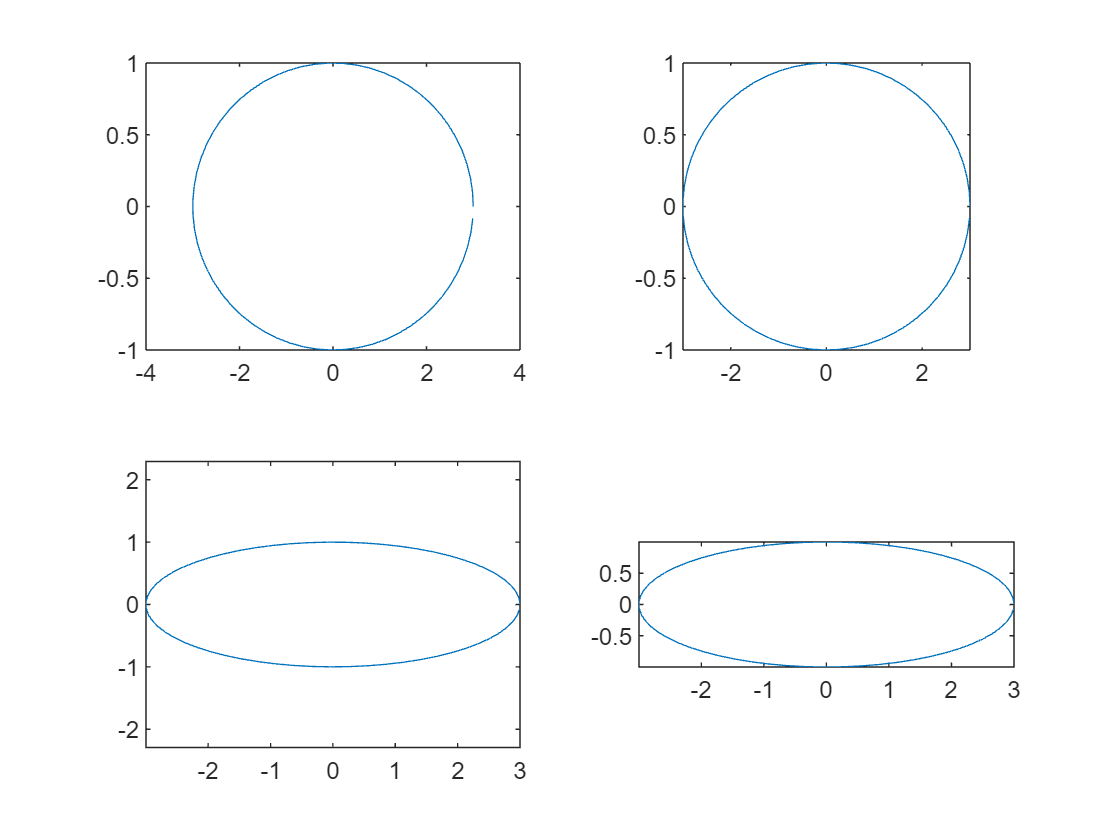

t = 0:0.1:2*pi; x = 3*cos(t); y = sin(t);
subplot(2, 2, 1); plot(x, y); axis normal
subplot(2, 2, 2); plot(x, y); axis square
subplot(2, 2, 3); plot(x, y); axis equal
subplot(2, 2, 4); plot(x, y); axis equal tight

## 绘制多条图线

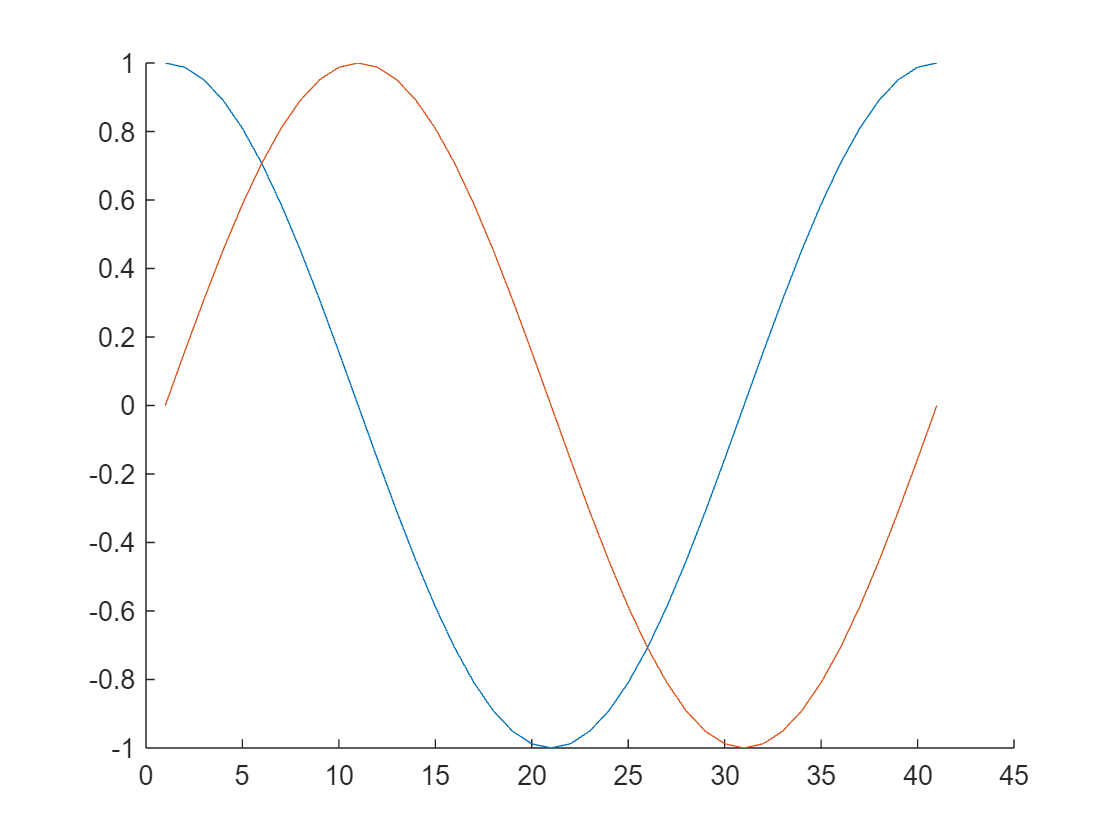

subplot(1, 1, 1); % 重置网格
hold on		% 提起画笔,开始绘制一组图片			
plot(cos(0:pi/20:2*pi));
plot(sin(0:pi/20:2*pi));
hold off	% 放下画笔,该组图片绘制完毕

## 在一个窗口内绘制多个图像

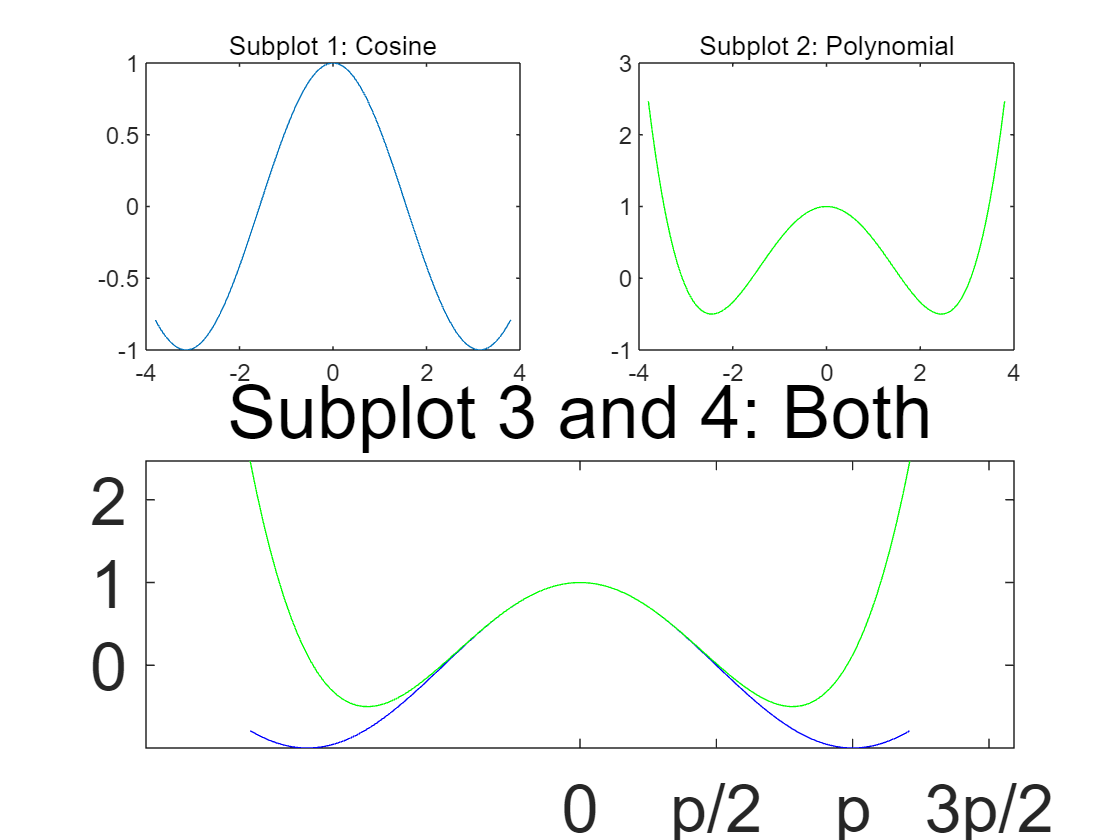

subplot(2,2,1);
x = linspace(-3.8,3.8);
y_cos = cos(x);
plot(x,y_cos);
title('Subplot 1: Cosine')

subplot(2,2,2);
y_poly = 1 - x.^2./2 + x.^4./24;
plot(x,y_poly,'g');
title('Subplot 2: Polynomial')

subplot(2,2,[3,4]); % 其中的第三格和第四格

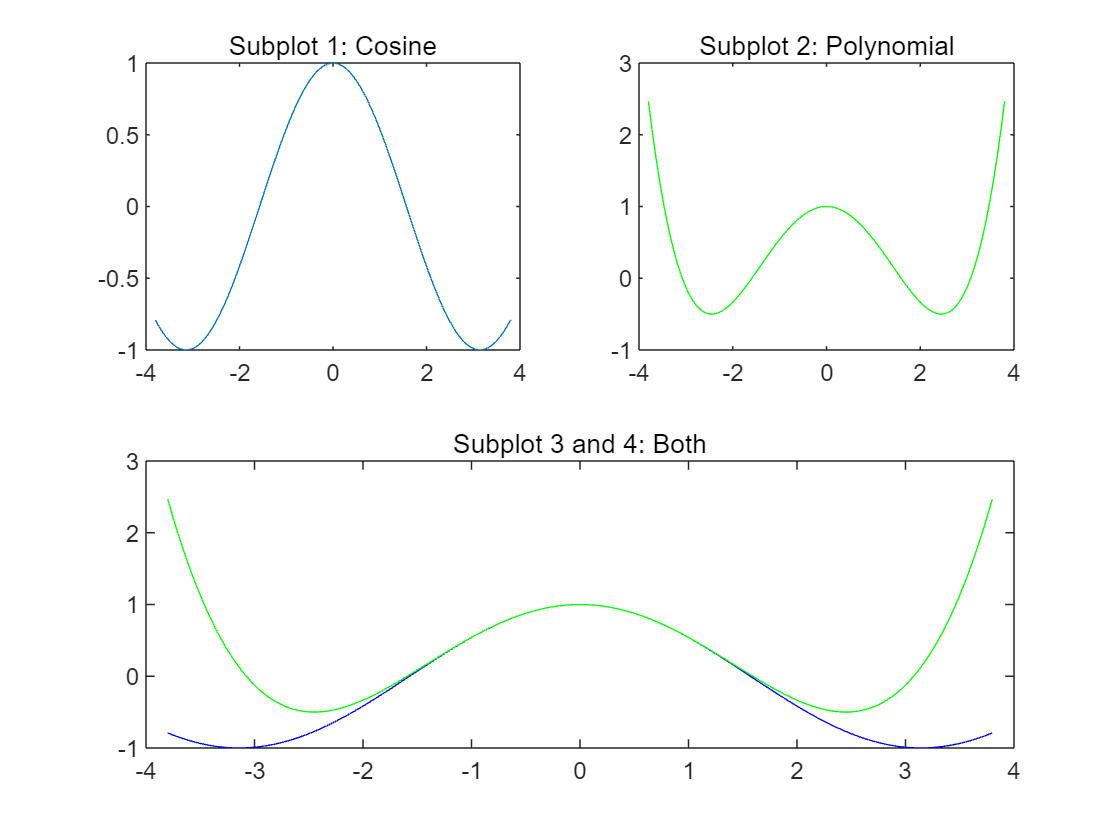

plot(x,y_cos,'b',x,y_poly,'g'); % 两张图叠加 b-蓝色 g-绿色
title('Subplot 3 and 4: Both')

## 图形对象的操作

`set(H,Name,Value) % H - 句柄;Name - 属性;Value - 属性值`

        gca()        获取当前坐标轴的句柄

`    gcf()    `获取当前图像的句柄

一、改变坐标轴属性

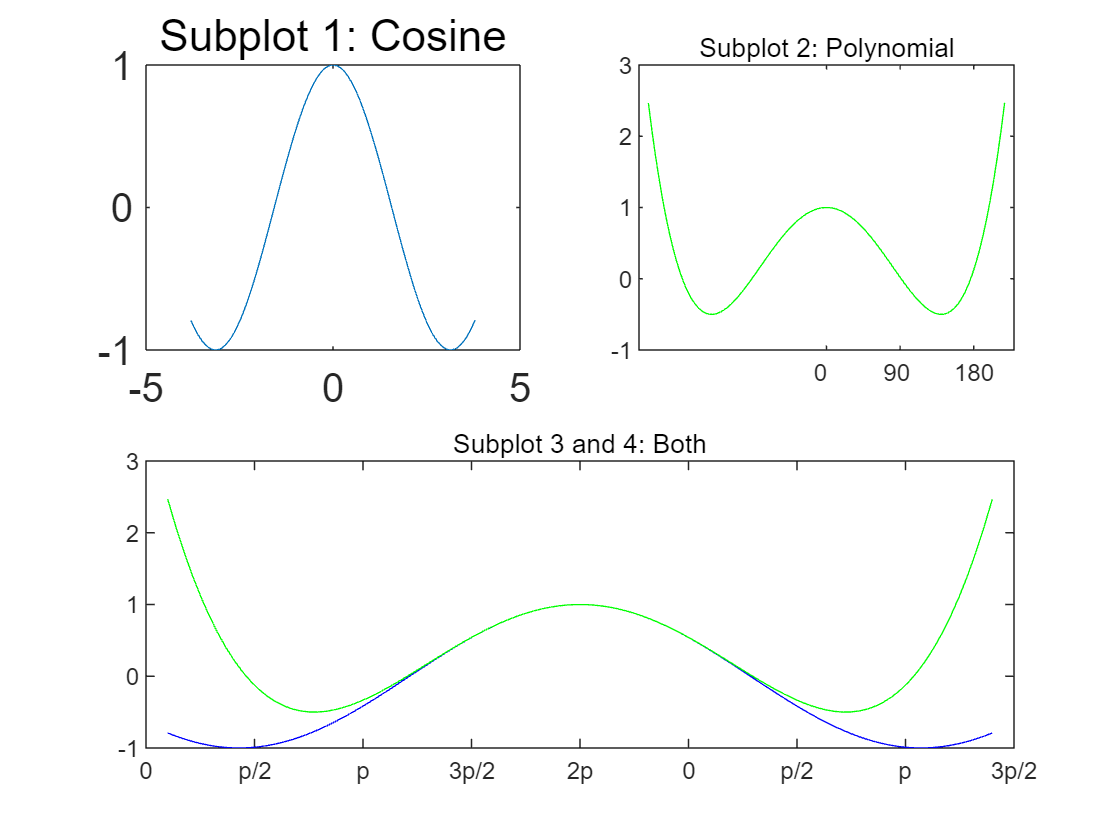

subplot(2,2,1);
% 第一张图
set(gca, 'FontSize', 15); % 字体大小

subplot(2,2,2);
% 第二张图
set(gca, 'XTick', 0:pi/2:2*pi);
set(gca, 'XTickLabel', 0:90:360);

subplot(2,2,[3,4]);
% 第三张图
set(gca, 'XTickLabel', {'0', 'p/2', 'p', '3p/2', '2p'});

## 二维图表

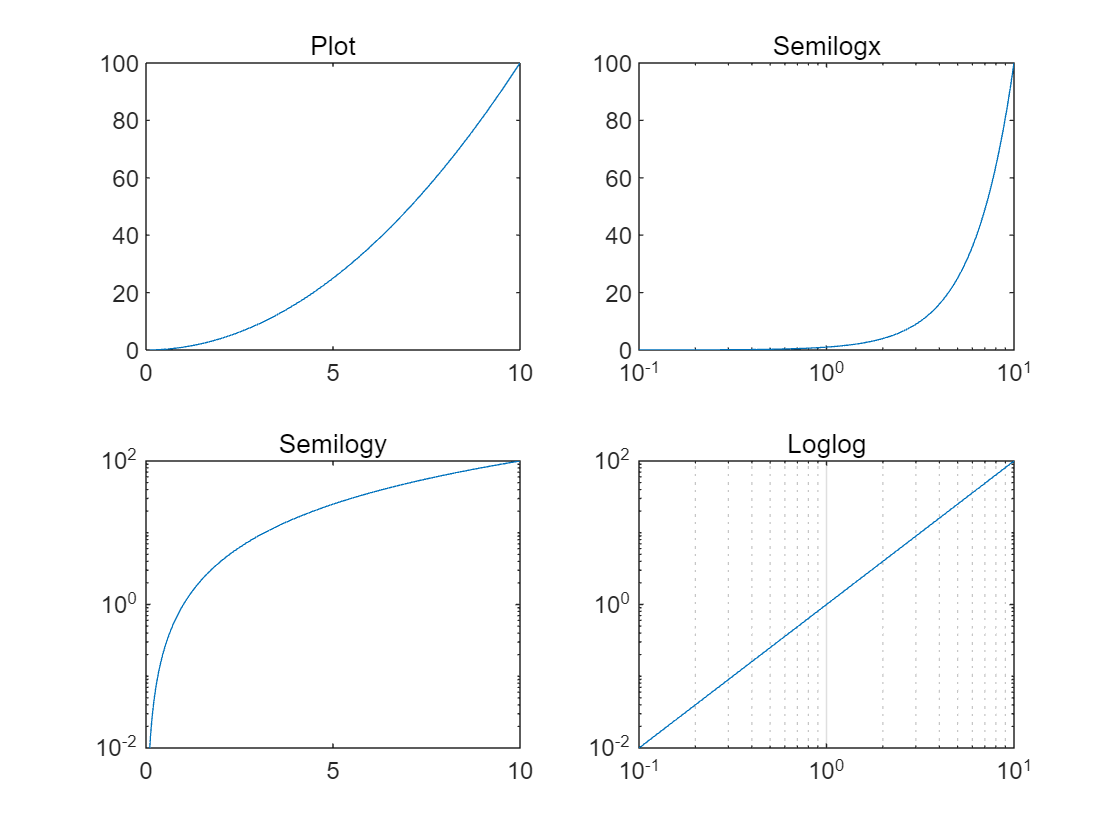

x = logspace(-1,1,100); y = x.^2;

subplot(2,2,1);
plot(x,y);      % 线性坐标
title('Plot');

subplot(2,2,2);
semilogx(x,y);  % x轴取对数坐标,y轴取线性坐标
title('Semilogx');

subplot(2,2,3);
semilogy(x,y);  % x轴取线性坐标,y轴取对数坐标
title('Semilogy');

subplot(2,2,4);
loglog(x, y);   % x轴和y轴都取对数坐标
title('Loglog')

% 对数坐标系可以加上网格,以区分线性坐标系与对数坐标系.
set(gca, 'XGrid','on')

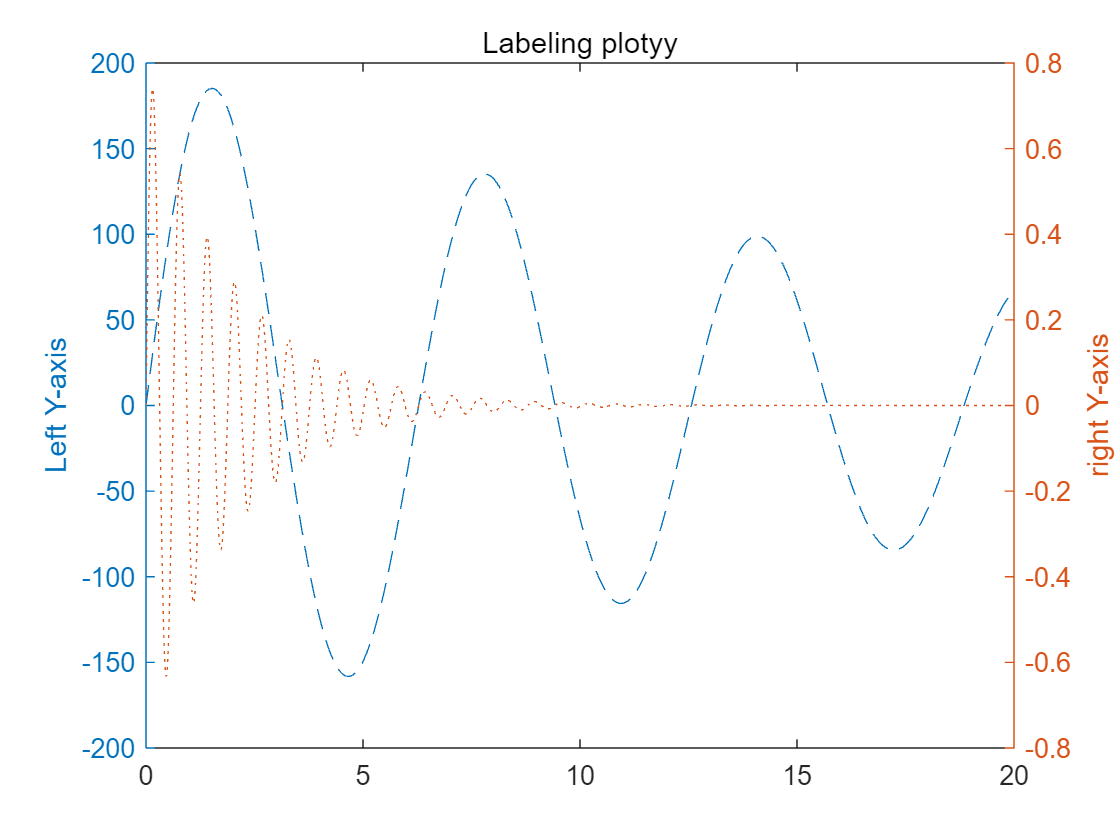

% 双y轴图线
subplot(1,1,1);
x = 0:0.01:20;
y1 = 200*exp(-0.05*x).*sin(x);
y2 = 0.8*exp(-0.5*x).*sin(10*x);
% 左边
yyaxis left
plot(x,y1,'--');
ylabel('Left Y-axis');
% 右边
yyaxis right
plot(x,y2,':');
ylabel('right Y-axis');
% 标题
title('Labeling plotyy');

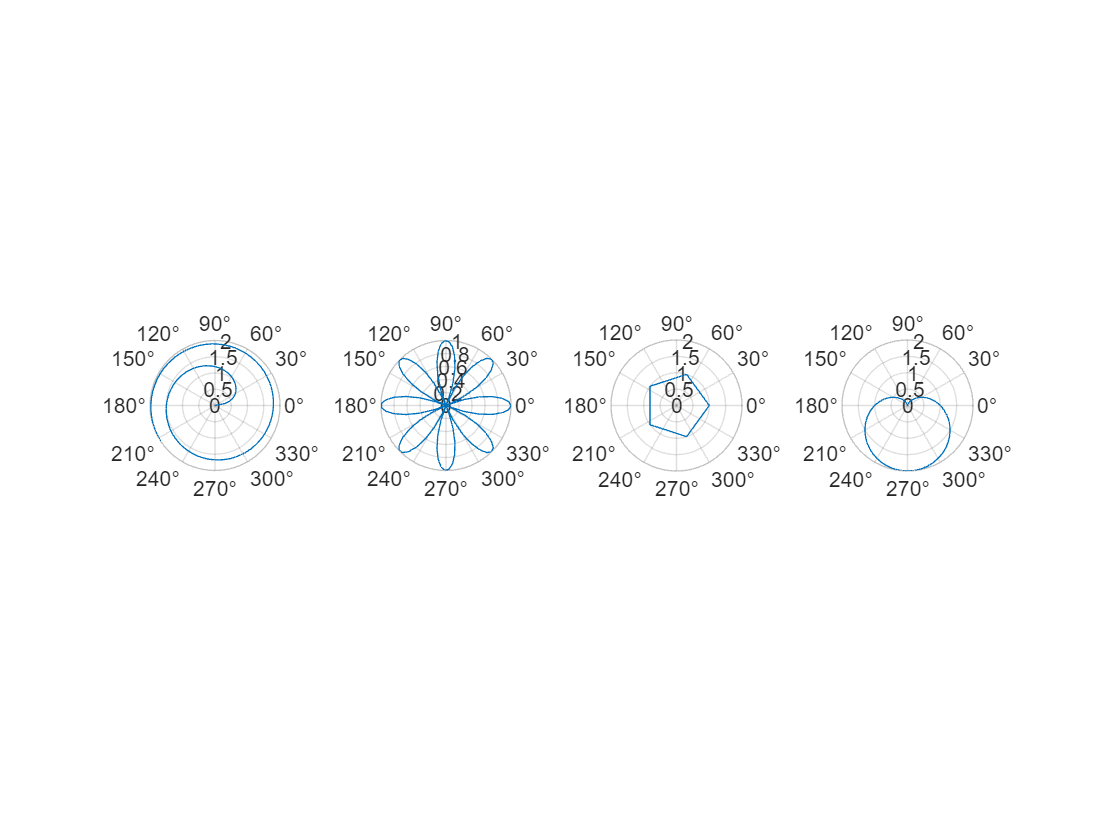

% [AX,H1,H2] = plotyy(x,y1,x,y2);
% set(get(AX(1),'Ylabel'),'String','Left Y-axis')
% set(get(AX(2),'Ylabel'),'String','Right Y-axis')
% title('Labeling plotyy');
% set(H1,'LineStyle','--'); set(H2,'LineStyle',':');

% 极坐标图线
% 螺旋线
x = 1:100; theta = x/10; r = log10(x);
subplot(1,4,1); polarplot(theta,r);

% 花瓣
theta = linspace(0, 2*pi); r = cos(4*theta);
subplot(1,4,2); polarplot(theta, r);

% 五边形
theta = linspace(0, 2*pi, 6); r = ones(1,length(theta));
subplot(1,4,3); polarplot(theta,r);

% 心形线
theta = linspace(0, 2*pi); r = 1-sin(theta);
subplot(1,4,4); polarplot(theta , r);

## 统计图表

- hist()	直方图

- bar()	二维柱状图

- pie()    	饼图

- stairs()	阶梯图

- stem()	针状图

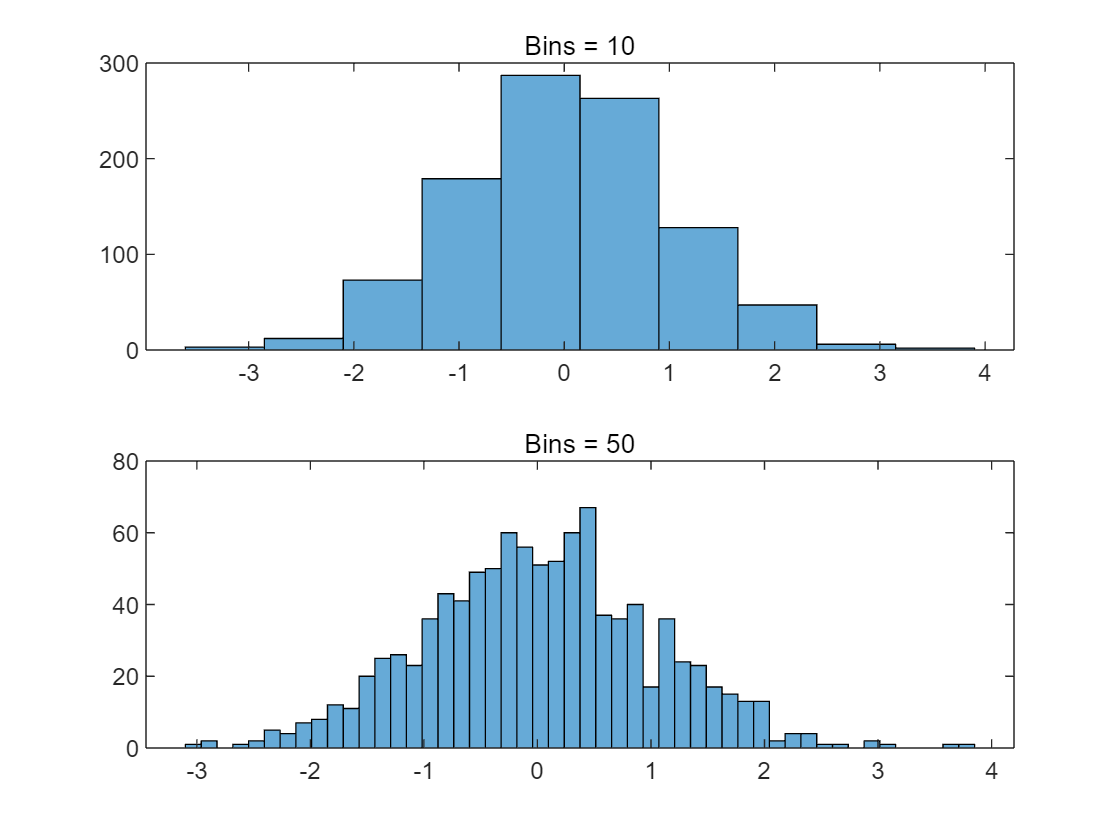

% 直方图
% hist(x,nbins) % x - 原始数据;nbins - 分组个数
x = randn(1,1000);

% 10组
subplot(2,1,1);
% hist(x,10);
histogram(x,10);
title('Bins = 10');

% 50组
subplot(2,1,2);
% hist(x,50);
histogram(x,50)
title('Bins = 50');

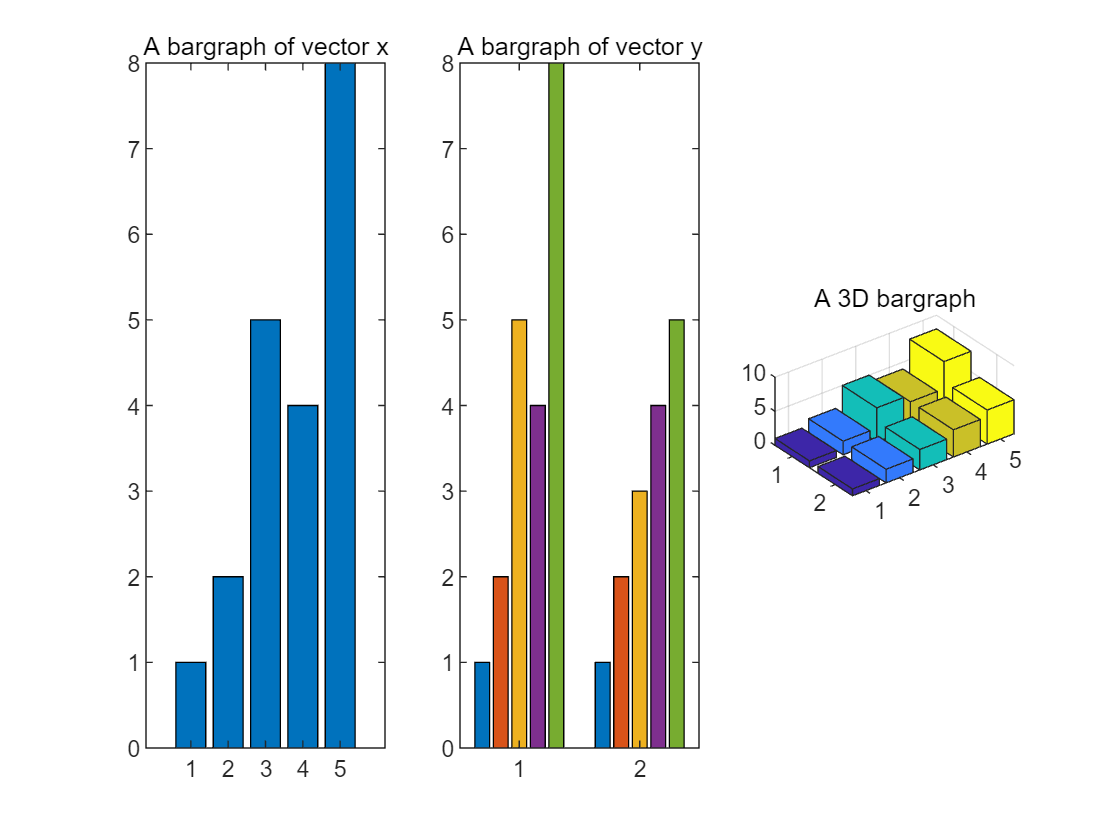

% 柱状图
% 使用bar()和bar3()函数分别绘制二维和三维直方图
x = [1 2 5 4 8]; y = [x;1:5];
subplot(1,3,1); bar(x); title('A bargraph of vector x');
subplot(1,3,2); bar(y); title('A bargraph of vector y');
subplot(1,3,3); bar3(y); title('A 3D bargraph');

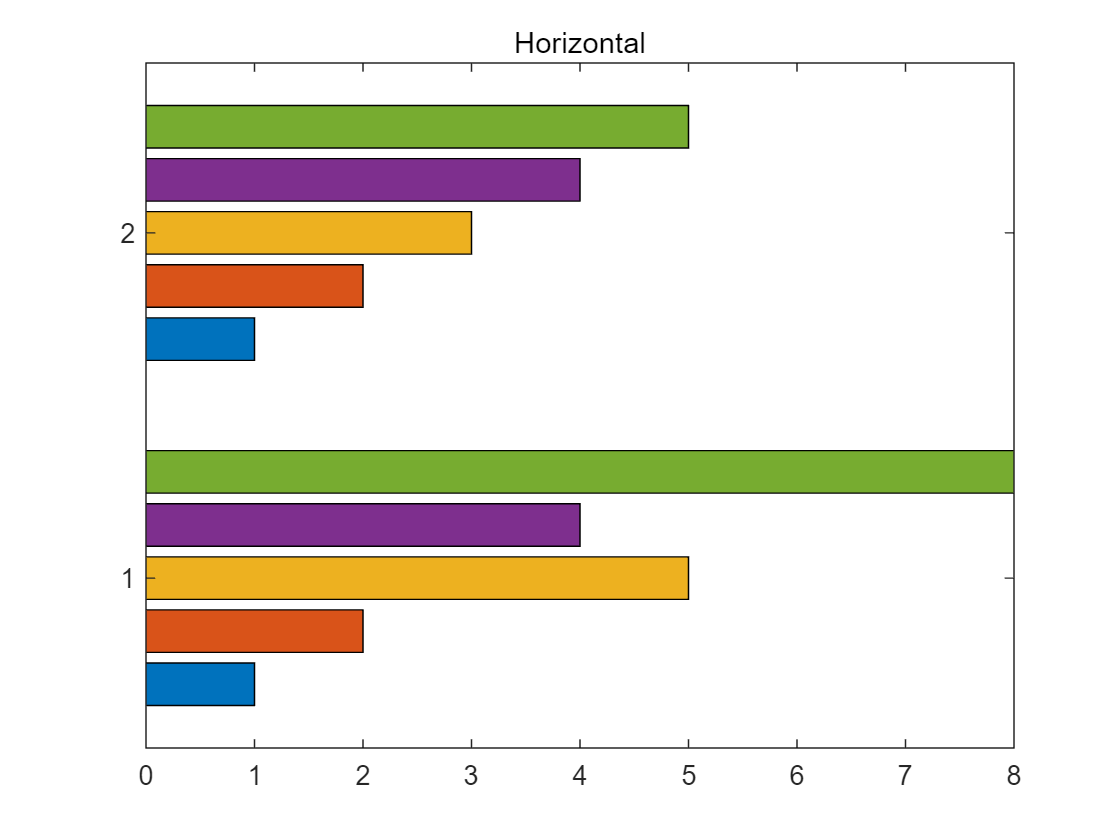

figure
% 使用barh()函数可以绘制纵向排列的柱状图
x = [1 2 5 4 8];
y = [x;1:5];    % 二维数组
barh(y);
title('Horizontal');

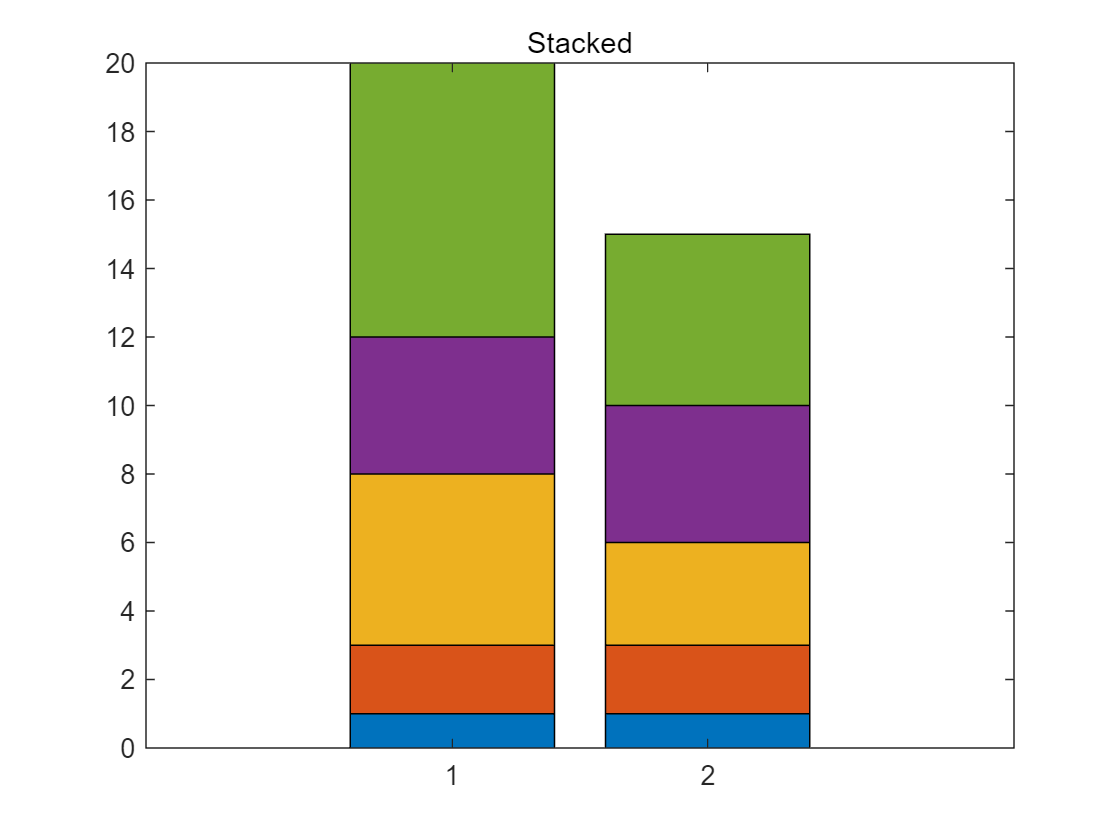

figure
% 向bar()传入'stack'参数可以让柱状图以堆栈的形式画出.
x = [1 2 5 4 8];
y = [x;1:5];
bar(y,'stacked');
title('Stacked');

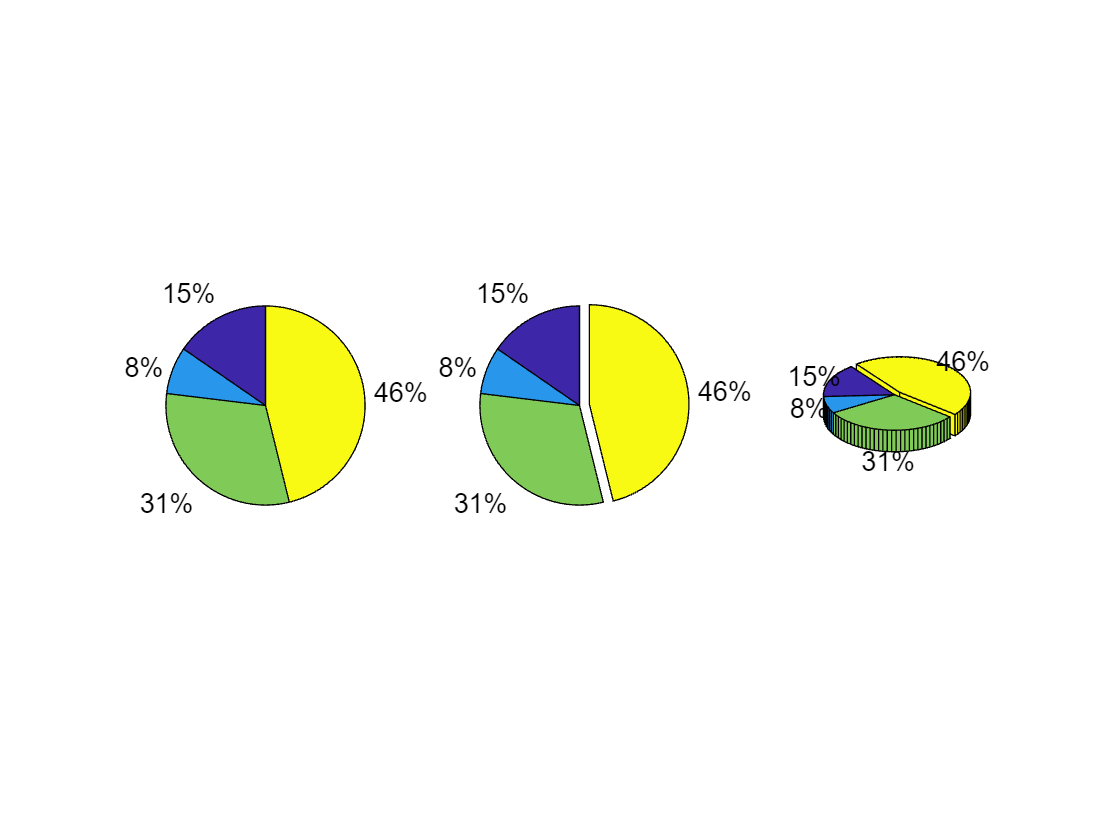

% 饼图
% 使用pie()和pie3()可以绘制二维和三维的饼图.向其传入一个bool向量表示每一部分扇区是否偏移.
figure
a = [10 5 20 30];
subplot(1,3,1); pie(a);
subplot(1,3,2); pie(a, [0,0,0,1]); % 1 表示分割
subplot(1,3,3); pie3(a, [0,0,0,1]);

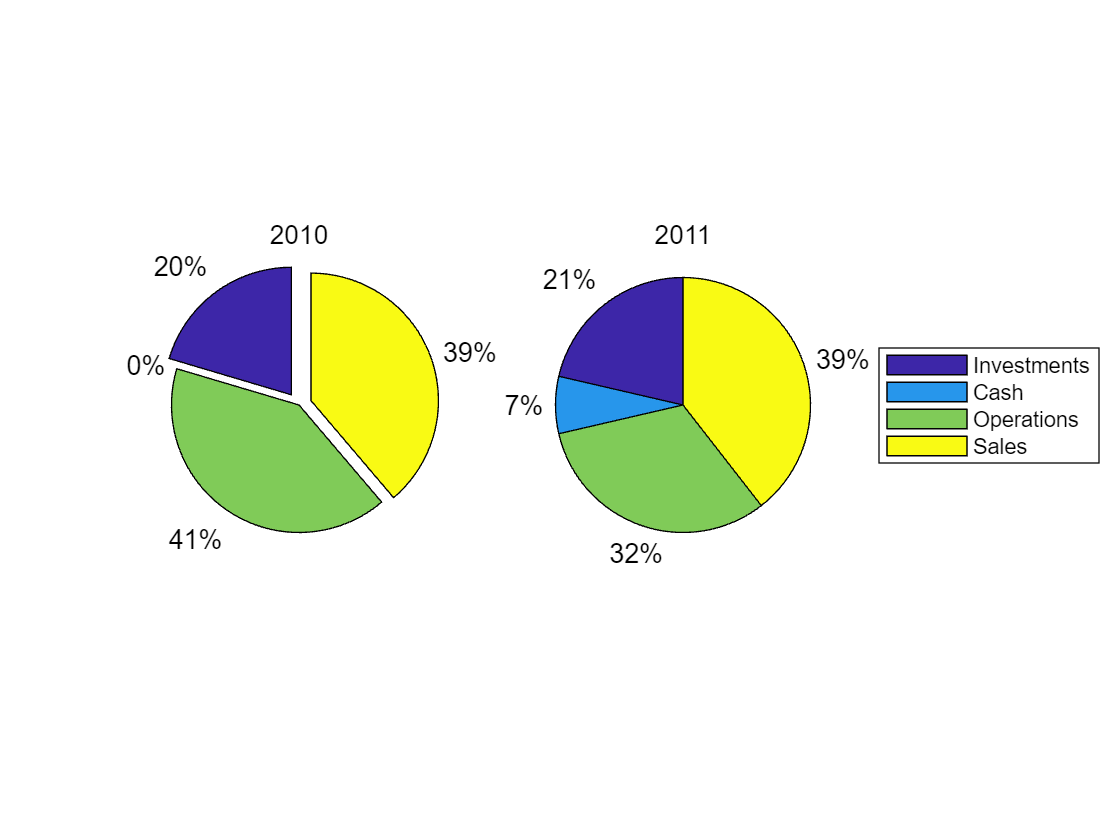

figure
y2010 = [50 0 100 95];
y2011 = [65 22 97 120];
labels = {'Investments','Cash','Operations','Sales'};
t = tiledlayout(1,2,'TileSpacing','compact');   % 创建分块图布局   1行2列    

% Create pie charts
ax1 = nexttile();     % 通过调用 nexttile 函数，在第一个图块中创建一个坐标区对象
pie(ax1,y2010,[1,0,0,1])
title('2010')

ax2 = nexttile();
pie(ax2,y2011)
title('2011')

% Create legend
lgd = legend(labels);
lgd.Layout.Tile = 'east'; % 将图例放置右边